# **E3.5**

First we will generate a 50 vectors from each class with the specifications:


$$\mu_1^T =\left\lbrack 1,1\right\rbrack ,\mu_2^T =\left\lbrack 0,0\right\rbrack ,\sigma_1^2 =\sigma_2^2 =0\ldotp 2$$


We will the helper function Gaussian_Data_Gen to generate these samples:

mu1 = [1; 1];
mu2 = [0; 0];   
mu = cat(2, mu1, mu2);
s = [0.2, 0; 0, 0.2];
sigma = cat(3, s, s);
% mu -> c x l
mu = permute(mu, [2, 1]);
% sigma -> c x l x l
sigma = permute(sigma, [3, 1, 2]);
% 100 samples, 50 from each
P = [1/2; 1/2];
N = 100;
[X, y_true] = Gaussian_Data_Gen(mu,sigma,P,N);

Now we will disregard vectors with $x_1 +x_2 <1$for class 1($\left\lbrack 1,1\right\rbrack$) and $x_1 +x_2 >1$ for class 2($\left\lbrack 0,0\right\rbrack$):

remove_idx = [];
for i=1:N
    if (y_true(i) == 1 && X(i,1) + X(i,2) < 1) || (y_true(i) == 2 && X(i,1) + X(i,2) > 1)
        remove_idx = [remove_idx; i];
    end
end
X(remove_idx,:) = [];
y_true(remove_idx) = [];

We will now verify that the problem is linearly seperable by plotting samples from both classes:

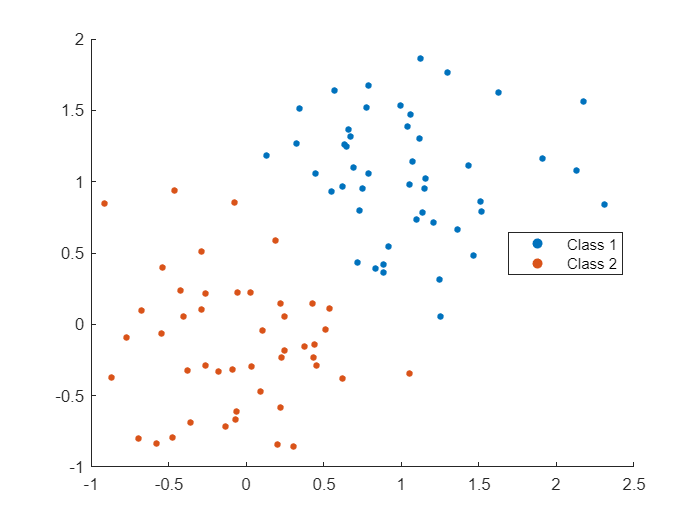

scatter(X(y_true == 1, 1), X(y_true == 1, 2), 15, 'filled');
hold on
scatter(X(y_true == 2, 1), X(y_true == 2, 2), 15, 'filled');
legend('Class 1', 'Class 2', 'Location', 'best')
hold off

As we can see, we have now forced the generated data points to be be linearly seperable. Next up, we will train a perceptron to form a decision boundary between these two classes.

% augment the training data with a vector of "1"s
X_aug = [X, ones([size(X,1), 1])];
% set initial weights to a standard normal value
w = normrnd(0, 1, [3, 1]);
% convergence flag
converged = false;
% learning rate
rho = 0.5;
% the perceptron algorithm main loop
iteration = 1;
while true
    % index of the input of the current iteration
    input_idx = mod(iteration, size(X_aug,1)) + 1;
    % calculate output of perceptron
    output = w'*X_aug(input_idx,:)';
    if y_true(input_idx) == 1 && output <= 0
        % misclassified sample from class 1
        w = w + rho*X_aug(input_idx,:)';
    elseif y_true(input_idx) == 2 && output >= 0
        % misclassified sample from class 2
        w = w - rho*X_aug(input_idx,:)';
    end
    % check for convergence
    % because the perceptron algorithm guarantees perfect convergence after
    % finitely many steps given a linearly separable problem, we will check
    % for convergence every time after seeing the entire dataset
    if mod(iteration, size(X_aug,1)) == 0
        iteration
        w
        converged = true;
        for i=1:size(X_aug,1)
            output = w'*X_aug(i,:)';
            if (y_true(i) == 1 && output <= 0) || (y_true(i) == 2 && output >= 0)
                converged = false;
                break;
            end
        end
    end
    if converged
        break;
    end
    iteration = iteration + 1;
end

iteration = 93

w =     0.6815
    0.9000
   -0.2301


iteration = 186

w =     0.7186
    0.4746
   -0.7301


iteration = 279

w =     0.6963
    0.6146
   -1.2301


iteration = 372

w =     0.6146
    0.9957
   -1.2301


iteration = 465

w =     1.0951
    0.7798
   -1.2301


iteration = 558

w =     1.1977
    0.9462
   -1.2301


fprintf('Converged in %d steps.', iteration);

Converged in 558 steps.

disp('Final weights:');

Final weights:


w

w =     1.1977
    0.9462
   -1.2301


Finally we can draw the decision boundary to verify that it perfectly classifies both classes.

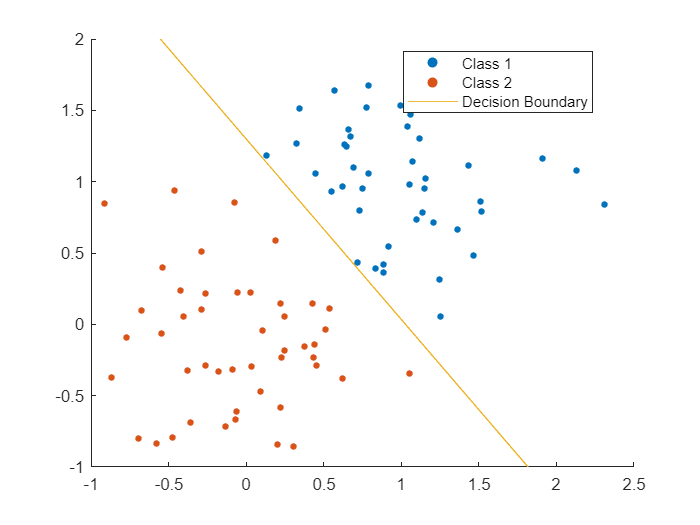

scatter(X(y_true == 1, 1), X(y_true == 1, 2), 15, 'filled');
hold on
scatter(X(y_true == 2, 1), X(y_true == 2, 2), 15, 'filled');
hold on
syms x real
decision_boundary = -(w(1)*x + w(3))/w(2);
axis manual
fplot(decision_boundary);
legend('Class 1', 'Class 2', 'Decision Boundary', 'Location', 'best')
hold off